## Exercise on System Step Response.

#### Data

% Data set 1: the system converges slowly and smoothly to the steady state value of 10.
R = 10;
L = 1;
C = 1;

% Data set 2: the system reaches the steady state value of 0.5 faster, but with some fluctuations.
% R = 0.5;
% L = 1;
% C = 1;

#### State Space Representation.

A = [0 1/C; -1/L -R/L];
B = [1; 0];
C = [1 0];
D = 0;

sys = ss(A,B,C,D);
x0 = [1; 0];

#### Run and plot the Step Response.

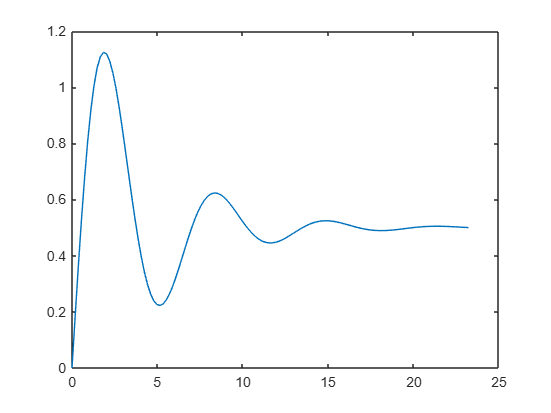

[y, t, x] = step(sys);

plot(t,y);

#### Calculate the Poles.

pole(sys)

ans =   -0.2500 + 0.9682i
  -0.2500 - 0.9682i
